clc; clear; close all;

lion = imread('LionImage.jpg');
lionNV = imread('LionImageNightVision.jpg');

B = imresize(lion,[589 943]) 

B = 589×943×3 uint8 array
B(:,:,1) =

    39    41    44    45    48    51    52    51    51    50    46    38    35    36    35    33    32    33    33    33    30    27    25    25    25    24    24    25    26    26    26    27    29    32    32    33    37    40    41    42    47    51    52    52    54    58    59    55    56    59    61    63    63    66    68    68    68    69    69    71    72    74    77    77    78    79    80    81    82    81    80    80    83    87    94   101   106   111   116   122   130   136   139   137   132   131   132   132   125   123   122   118   114   111   106   103    99    94    91    86    86    86    85    83    81    80    76    72    69    63    54    47    41    33    31    29    27    27    29    29    29    29    30    28    28    28    31    31    30    29    28    29    30    29    28    27    27    27    26    25    25    26    26    26    27    27    27    27    27    27    26    24    22    23    22    23    22    22    20    19  

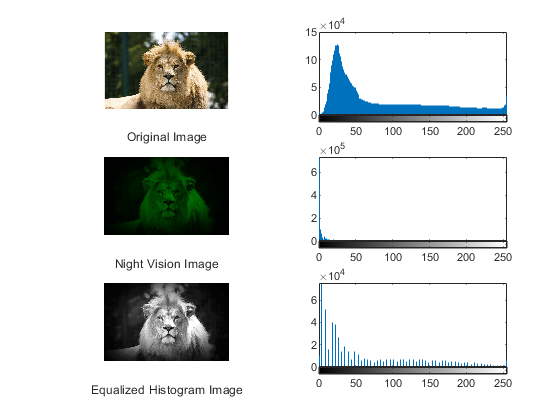

imwrite(B, "LionImage2.jpg", "Quality", 100) 

equal_img = imadjust(im2gray(lionNV));

subplot 321
imshow(lion); xlabel('Original Image');
subplot 322
imhist(lion); ylim('auto')
subplot 323
imshow(lionNV); xlabel('Night Vision Image');
subplot 324
imhist(lionNV); ylim('auto')
subplot 325
imshow(equal_img); xlabel('Equalized Histogram Image')
subplot 326
imhist(equal_img); ylim('auto')

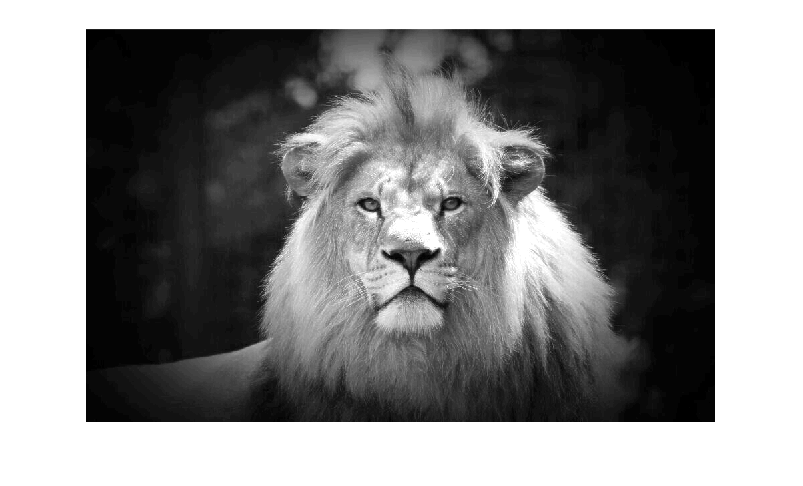


figure;
imshow(equal_img)


imwrite(equal_img, "AdjustedLionImage.jpg", "Quality", 100) 